## **Structure from motion formative assignment**

This task takes images taken of an object from several postions and anlyses them to establish the reltive postions of these camera locations. The data used in this task is availble curtosy of Mathworks Inc. An explanation of a similar code is available to watch at: [https://www.youtube.com/watch?v=pdNJUeg-oq8](https://www.youtube.com/watch?v=pdNJUeg-oq8)  We will also be running office hours on Fridays 1300-1400.

### Load the data

The data set used in this task is loaded as an image directory using the following command

% Use |imageDatastore| to get a list of all image file names in a directory.
imageDir = fullfile(toolboxdir('vision'), 'visiondata', 'structureFromMotion');

### Tasks

#### Question 1.1

Read the imageDir and create an approppriate datastore of all the images in the directory, justify your choice of datasore type. convert all images to grayscale and display the resulting images.

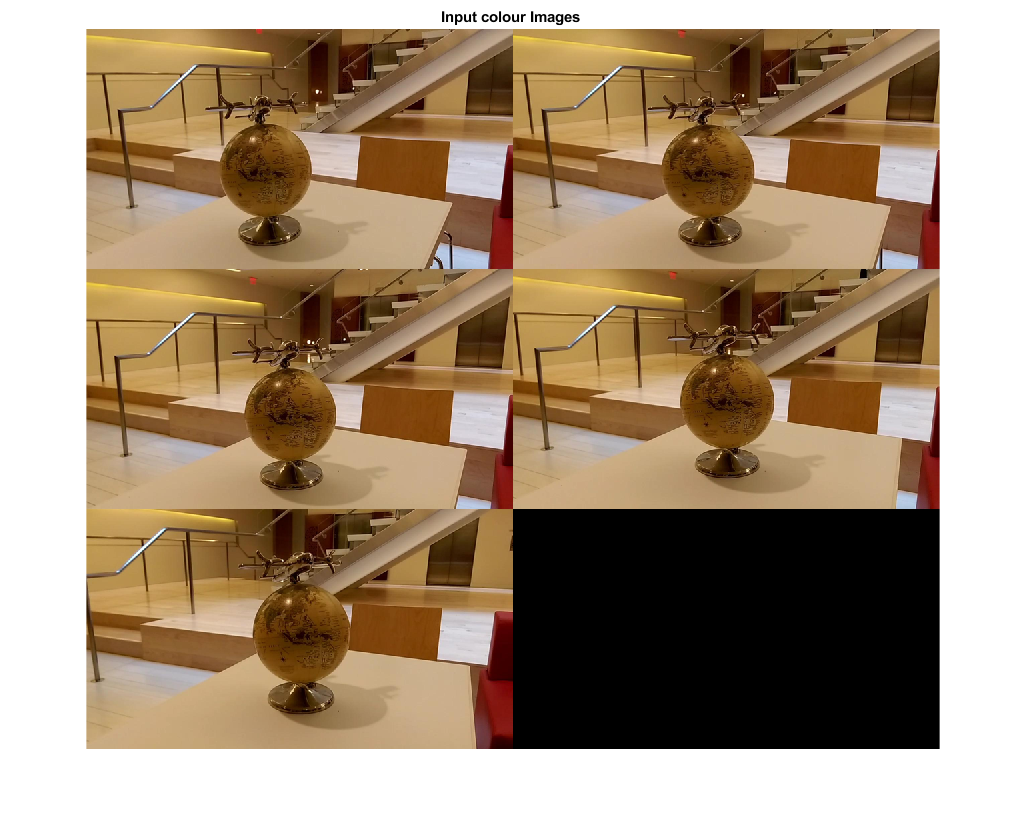

%Create an appropriate datastore. An imageDatastore is used in this case.
%Matlab has a choice of several datastore types for more information go to:
%https://uk.mathworks.com/help/matlab/import_export/what-is-a-datastore.html

imds = imageDatastore(imageDir);

% Display the original colour images.
figure
montage(imds.Files, 'Size', [3, 2]);
title('Input colour Images ');

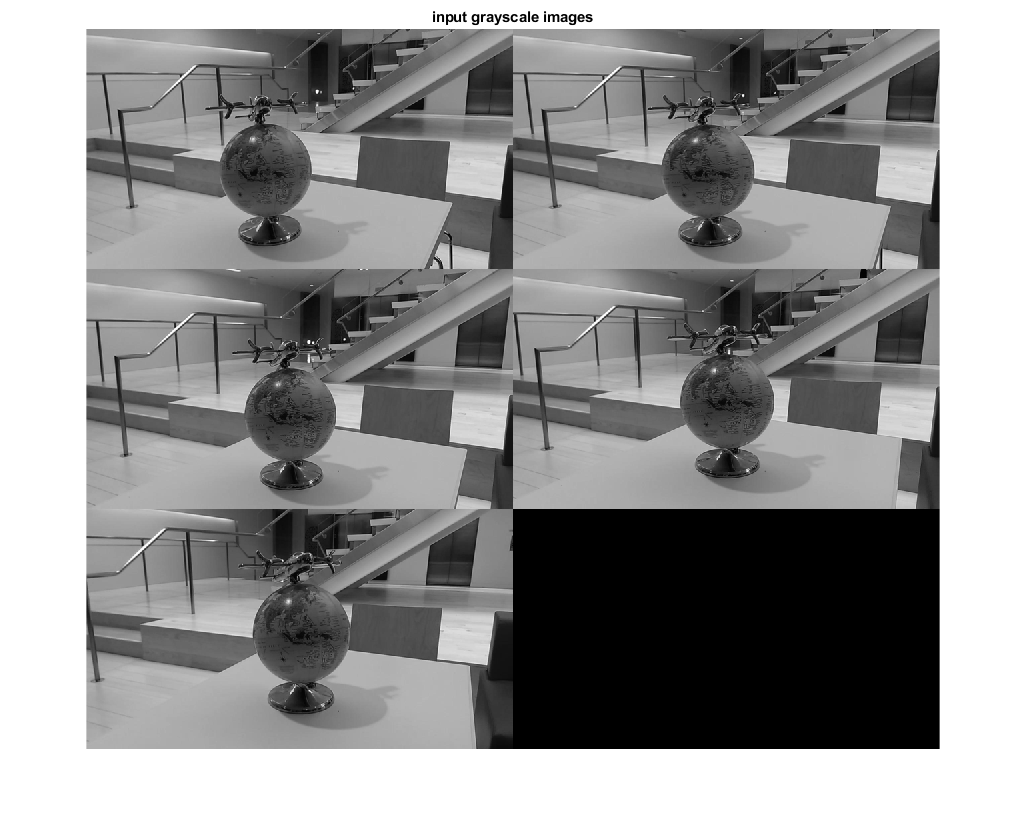


% Convert the images to grayscale.
images = cell(1, numel(imds.Files));
for i = 1:numel(imds.Files)
    I = readimage(imds, i);
    images{i} = rgb2gray(I);
end

%Display the grayscale images
figure
montage(images,'Size',[3,2]);
title('input grayscale images');

#### Question 1.2

Load the camera parametes (cameraParams.mat) from imagedir. open cameraparams.mat, you  should now be able to see a number of parameters which you will need for the rest of the task.

%load the camer parameters from the imageDir as a data set
data = load(fullfile(imageDir, 'cameraParams.mat'));

%assighn data.cameraParams to variable cameraParams
cameraParams = data.cameraParams;

#### Question 1.3

Extract key common featues from the images and estimate the camera position reliatve to the previous image. these changes in position should then be related in a global coordinate system, use bundle adjustment to refine all points. if you get stuck the script helperEstimateRelativePose can be used to realte the relative positions. 

*The approach shown here first carries out eh required operations on the first image and then applies it to the remaining images. It is also possible to shorten the code to simply do all the images at once.*

% Get intrinsic parameters of the camera
intrinsics = cameraParams.Intrinsics;

Unrecognized method, property, or field 'Intrinsics' for class 'cameraParameters'.


% Undistort the first image.
I = undistortImage(images{1}, intrinsics); 

% Detect features. Increasing 'NumOctaves' helps detect large-scale
% features in high-resolution images. Use an ROI to eliminate spurious
% features around the edges of the image.
border = 50;
roi = [border, border, size(I, 2)- 2*border, size(I, 1)- 2*border];
prevPoints   = detectSURFFeatures(I, 'NumOctaves', 8, 'ROI', roi);

% Extract features. Using 'Upright' features improves matching, as long as
% the camera motion involves little or no in-plane rotation, which is true in this task.
prevFeatures = extractFeatures(I, prevPoints, 'Upright', true);

% Create an empty imageviewset object to manage the data associated with each
% view. Creating an empty varibale to mange the data speeds up processing
% time.
vSet = imageviewset;

% Add the first view. Place the camera associated with the first view
% and the origin, oriented along the Z-axis.
%The viewID variable identifies the camera view 
viewId = 1;
vSet = addView(vSet, viewId, rigid3d, 'Points', prevPoints);

%The process is now aplied to all of the images in the dataset using a loop
%function

for i = 2:numel(images)
    % Undistort the current image.
    I = undistortImage(images{i}, intrinsics);
    
    % Detect, extract and match features.
    currPoints   = detectSURFFeatures(I, 'NumOctaves', 8, 'ROI', roi);
    currFeatures = extractFeatures(I, currPoints, 'Upright', true);    
    indexPairs   = matchFeatures(prevFeatures, currFeatures, ...
        'MaxRatio', .7, 'Unique',  true);
    
    % Select matched points.
    matchedPoints1 = prevPoints(indexPairs(:, 1));
    matchedPoints2 = currPoints(indexPairs(:, 2));
    
    % Estimate the camera pose of current view relative to the previous view.
    % The pose is computed up to scale, meaning that the distance between
    % the cameras in the previous view and the current view is set to 1.
    % This will be corrected by the bundle adjustment.
    [relativeOrient, relativeLoc, inlierIdx] = helperEstimateRelativePose(...
        matchedPoints1, matchedPoints2, intrinsics);
    
    % Get the table containing the previous camera pose.
    prevPose = poses(vSet, i-1).AbsolutePose;
    relPose  = rigid3d(relativeOrient, relativeLoc);
        
    % Compute the current camera pose in the global coordinate system 
    % relative to the first view.
    currPose = rigid3d(relPose.T * prevPose.T);
    
    % Add the current view to the view set.
    vSet = addView(vSet, i, currPose, 'Points', currPoints);

    % Store the point matches between the previous and the current views.
    vSet = addConnection(vSet, i-1, i, relPose, 'Matches', indexPairs(inlierIdx,:));
    
    % Find point tracks across all views.
    tracks = findTracks(vSet);

    % Get the table containing camera poses for all views.
    camPoses = poses(vSet);

    % Triangulate initial locations for the 3-D world points.
    xyzPoints = triangulateMultiview(tracks, camPoses, intrinsics);
    
    % Refine the 3-D world points and camera poses.
    [xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(xyzPoints, ...
        tracks, camPoses, intrinsics, 'FixedViewId', 1, ...
        'PointsUndistorted', true);

    % Store the refined camera poses.
    vSet = updateView(vSet, camPoses);

    prevFeatures = currFeatures;
    prevPoints   = currPoints;  
end

#### Question 1.4

Plot the relative camera positions and 3-D features you have calculated, ensuring your graph is fully labelled and titled


% Display camera poses.
camPoses = poses(vSet);
figure;
plotCamera(camPoses, 'Size', 0.2);
hold on

% Exclude noisy 3-D points.
goodIdx = (reprojectionErrors < 5);
xyzPoints = xyzPoints(goodIdx, :);

% Display the 3-D points.
pcshow(xyzPoints, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
    'MarkerSize', 45);
grid on
hold off

% Specify the viewing volume.
loc1 = camPoses.AbsolutePose(1).Translation;
xlim([loc1(1)-5, loc1(1)+4]);
ylim([loc1(2)-5, loc1(2)+4]);
zlim([loc1(3)-1, loc1(3)+20]);
camorbit(0, -30);

%label your graph
xlabel('X');
ylabel('Y');
zlabel('Z');

%title your graph
title('Relative camera postions');